# Exam August 2018

## Problem 1: Compute PSD from data using Pisarenko (sinusoid with additive white noise)

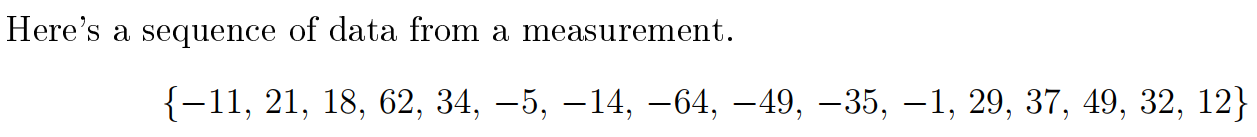

### [✔] 1) Compute and plot the autocorrelation for lags 0 to 4

x = [-11, 21, 18, 62, 34, -5, -14, -64, -49, -35, -1, 29, 37, 49, 32, 12];

% Estimate autocorrelation using data
[r_xx, ell] = xcorr(x, 'biased');

% Print out the lags 0 to 4
mid = floor(numel(ell)/2)+1;
r_xx(mid:mid+4)

ans = 	1.0e+03 *

    1.2256    0.8664    0.3979   -0.2310   -0.7027


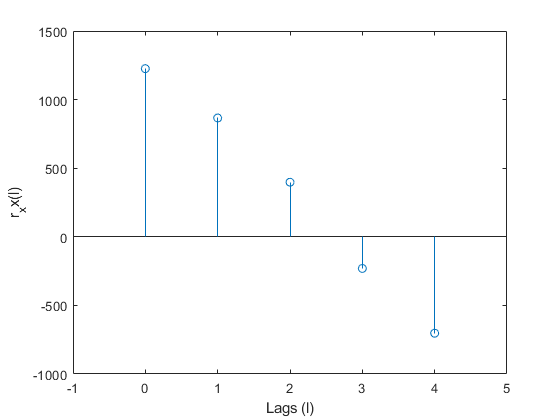

% Plot the results
stem(0:4, r_xx(mid:mid+4))
xlim([-1, 5])
xlabel('Lags (l)')
ylabel('r_xx(l)')

### [✔] 2) Compute the power spectral density assuming a Pisarenko model.

*Assume that the signal is a sinusoid in additive white Gaussian noise.*

The Pisarenko method can be used to recover the sinusoidal frequencies of a corrupted signal $x\left(n\right)$ given two assumptions:

- The signal $x\left(n\right)$ consists of $p$ sinusoids that has been corrupted by white noise.

- The autocorrelation matrix of size $\left(p+1\right)\times \left(p+1\right)$ is known or can be estimated from data

The Pisarenko method consists of the following steps:

***Step 1***: Compute the autocorrelation matrix ${\mathbf{R}}_{\mathrm{xx}}$

***Step 2:*** Find the eigenvector corresponding to the smallest minimum eigenvalue. The elements of this eigenvector is the parameters of the $\mathrm{ARMA}\left(2p,2p\right)$ model 

***Step 3:*** Find the frequencies $\left\lbrace \;f_i \;\right\rbrace$ of the sinusoids. This can be done by computing the roots of the polynomial $A\left(z\right)$ in Eq. (14.5.4) in the book. This polynomial has $2p$ poles on the unit circle which correspond to the frequencies of the system.

        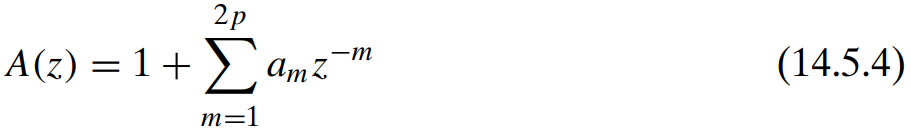

***Step 4*****:** Solve Eq. (14.5.11) for the signal powers $\left\lbrace P_i \right\rbrace$

        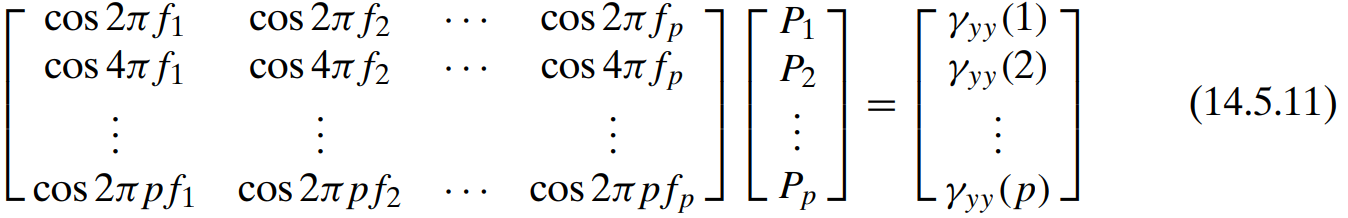

where 

- $\gamma_{\mathrm{yy}} \left(1\right),\gamma_{\mathrm{yy}} \left(2\right),\cdots ,\gamma_{\mathrm{yy}} \left(p\right)$ are the estimated autocorrelation values 

- $P_i =\frac{A_i^2 }{2}$ is the average power of the $i$th sinusoid and $A_i$ is the corresponding amplitude

***Step 5***: Estimate the amplitude $A_i =\sqrt{2P_i }$

These steps are coded up in the `pisarenko()` function (see at end of this document):

[F, A, P, lambda_min] = pisarenko(r_xx(mid:mid+4), 1)

F = 0.0938

A = 45.6585

P = 1.0423e+03

lambda_min = 183.2154

We can describe the signal as:

        
$$x\left(n\right)=45\ldotp 6585\;\cos \left(2\pi \cdot 0\ldotp 0938n\right)+w\left(n\right)$$


where $w\left(n\right)$ is white noise with variance $\sigma_w^2 =183\ldotp 2154$

To compute the power spectral density, we need to find the autocorrelation function of the sinusoid.

In ADSI Problem 4.4, we found that the autocorrelation of a real sinusoid given by $y\left(n\right)=A\;\mathrm{cos}\left(\omega n+\phi \right)$ where $A$ and $\omega$ are real constants and $\phi$ is a random variable with $\phi ~U\left(0,2\pi \right)$ is:

        
$$r_{\textrm{yy}} \left(\ell \right)=\frac{A^2 }{2}\mathrm{cos}\left(\omega \ell \right)$$


The autocorrelation function of white noise with variance $\sigma_w^2$ is given by:

        
$$r_{\mathrm{ww}} \left(\ell \right)=\sigma_w^2 \delta \left(\ell \right)$$


Combining these results, the general autocorrelation function of our signal is:

        
$$r_{\mathrm{xx}} \left(\ell \right)=\frac{A^2 }{2}\mathrm{cos}\left(\omega \ell \right)+\sigma_w^2 \delta \left(\ell \right)$$


The power spectral density is the Fourier transform the autocorrelation function which is given by:

        
$$S\left(\omega \right)=\frac{A^2 }{2}\pi \left\lbrack \delta \left(\omega -\omega_0 \right)+\delta \left(\omega +\omega_0 \right)\right\rbrack +\sigma_w^2$$


A, F, lambda_min

A = 45.6585

F = 0.0938

lambda_min = 183.2154

Using the values found via the Pisarenko, the PSD is:

        
$$S\left(\omega \right)=\frac{{\left(45\ldotp 6585\right)}^2 }{2}\pi \left\lbrack \delta \left(\omega -2\pi \cdot 0\ldotp 0938\right)+\delta \left(\omega +2\pi \cdot 0\ldotp 0938\right)\right\rbrack +183\ldotp 2154$$


Plot the PSD:

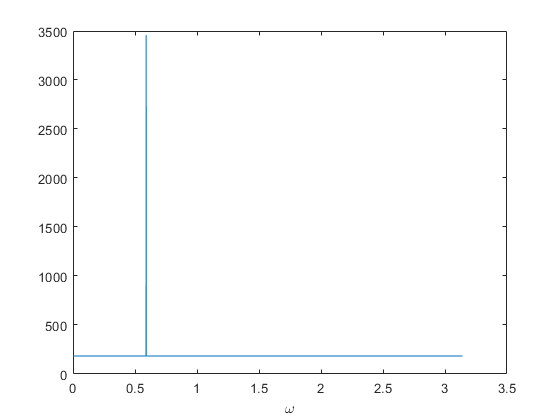

D = 3;
w = 0:10^(-D):pi;
delta = @(n) round(n, D) == 0;
S = (A^2/2)*pi * (delta(w-(F*2*pi)) + delta(w+(F*2*pi))) + lambda_min;
%plot(w/pi, real(pow2db(S)))
plot(w, S); 
xlabel('\omega')

### [✔] 3. Discuss whether the Pisarenko model can be considered appropriate for the given data.  

We can describe the signal as:

        
$$x\left(n\right)=45\ldotp 6585\;\cos \left(2\pi \cdot 0\ldotp 0938n\right)+w\left(n\right)$$


where $w\left(n\right)$ is white noise with variance $\sigma_w^2 =183\ldotp 2154$

The general autocorrelation function of that signal is:

        
$$r_{\mathrm{xx}} \left(\ell \right)=\frac{A^2 }{2}\mathrm{cos}\left(\omega \ell \right)+\sigma_w^2 \delta \left(\ell \right)$$


Considering the estimated autocorrelation of the data and the autocorrelation of the reconstruction, we can say that the Pisarenko model is appropriate.

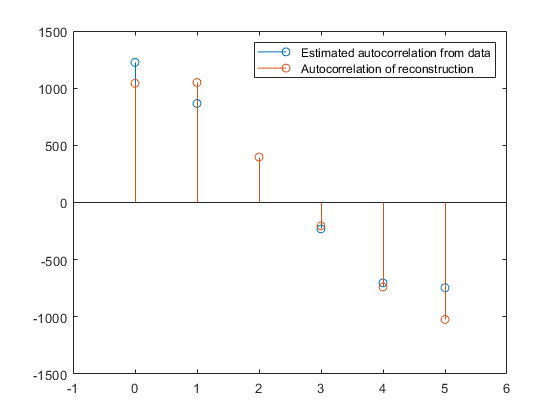

% Plot the autocorrelation function of the sinusoid
ell = 0:5;
r_ww = lambda_min * (ell == 1);
r_xx_p = (A^2/2) * cos(2*pi*F*ell) + r_ww;
stem(ell, r_xx(mid:mid+max(ell)))
hold on;
stem(ell, r_xx_p)
legend('Estimated autocorrelation from data', 'Autocorrelation of reconstruction')
xlim([min(ell)-1, max(ell)+1])
hold off;

In addition, plotting the limited amount of samples, we see a sinusiodal shape. Since Pisarenko model assumes sinuisoidal signal that has been corrupted by white noise then it can be appropriate model.

## Problem 2: True/False Questions

*For the statements given below, state whether they are true or false and justify your answer for each statement.  *

### [✔] 2) If a signal is scaled by 2, does its autocorrelation also scale by 2?

Answer: FALSE.

The autocorrelation of a signal $x\left(n\right)$ is defined as:

        
$$r_x \left(\ell \right)=E\left\lbrack x\left(n\right)x\left(n-\ell \right)\right\rbrack$$


We can compute the autocorrelation of signal $y\left(n\right)=2x\left(n\right)$ as follows:

        
$$r_y \left(\ell \right)=E\left\lbrack y\left(n\right)y\left(n-\ell \right)\right\rbrack$$


        
$$r_y \left(\ell \right)=E\left\lbrack 2\;x\left(n\right)2x\left(n-\ell \right)\right\rbrack$$


        
$$r_y \left(\ell \right)=4\cdot E\left\lbrack x\left(n\right)x\left(n-\ell \right)\right\rbrack$$


        
$$r_y \left(\ell \right)=4r_x \left(\ell \right)$$


### [?] 3) Under stationary conditions, a least mean square (LMS) adaptive filter with proper choice of the step-size will converge to the Wiener-Hopf solution.

## Problem 3: Matched Filters

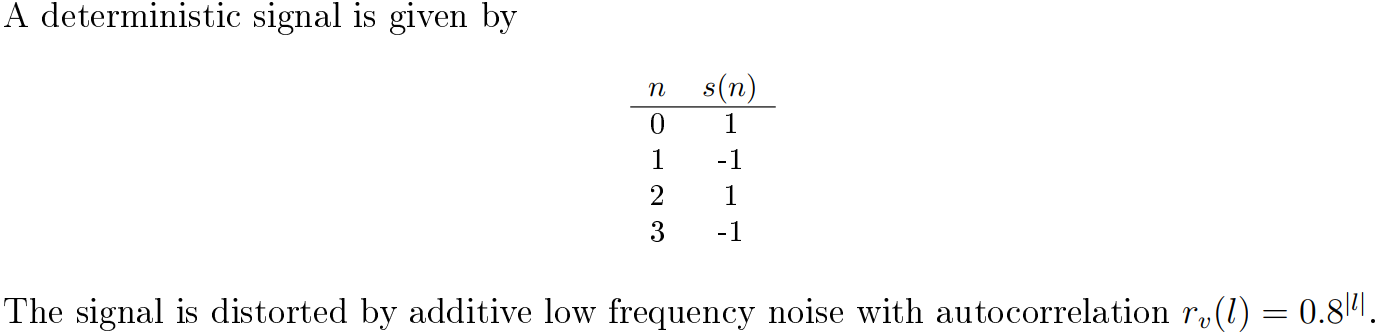

clear variables;

### [✔] 1) Design a matched filter to improve the signal to noise ratio and comment on the improvement.  

The impulse response of the matched filter is given by:

        

where $R_v$ is autocorrelation matrix of noise and $\kappa$ is the normalisation factor. 

Although the maximum SNR can be obtained by any choise of constant $\kappa$, we choose the constant by requiring that:

        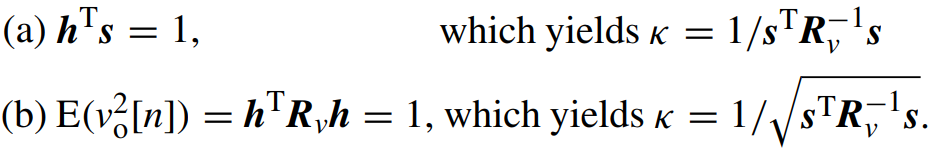

s = [1, -1, 1, -1]';

p = numel(s); % Signal length

% The autocorrelation matrix must be p x p since
% its inverse is multiplied by a p-tap signal s(n)
ell = 0:p-1;
r_vv = 0.8.^ell;
R_vv = toeplitz(r_vv);

% Compute normalisation factor (b)
k = 1/sqrt(s'*(R_vv\s)); % Same as 1/sqrt(s'*inv(R_vv)*s)

% Compute the filter
h = k*(R_vv\s); % Same as k*inv(R_vv)*s

% Print the matched filter coefficients
h

h =     0.9449
   -1.7008
    1.7008
   -0.9449


The optimum SNR is given by:

        

Assuming the attenuation factor $a=1$:

a = 1;
SNR = a^2 * s' * (R_vv\s)

SNR = 28.0000

### [✔] 2) Can the signal to noise ratio be improved by using more than two blocks?  

Yes, the SNR can be improved. With three blocks, the SNR is increased to 46:

s = [1, -1, 1, -1, 1, -1]';
p = numel(s);
ell = 0:p-1;
r_vv = 0.8.^ell;
R_vv = toeplitz(r_vv);
k = 1/sqrt(s'*(R_vv\s));
h = k*(R_vv\s);

a = 1;
SNR = a^2 * s' * (R_vv\s)

SNR = 46.0000

## Problem 4: Recover signal using a Wiener filter

### [✔] 1) Determine the autocorrelation function, $r_s \left(l\right)$

The output signal of the system is given as:

        
$$s\left(n\right)=4w\left(n\right)+w\left(n-1\right)$$


The autocorrelation of this signal is:

        
$$r_s \left(\ell \right)=E\left\lbrack s\left(n\right)s\left(n-\ell \right)\right\rbrack$$


                 
$$=E\left\lbrack \left(4x\left(n\right)+x\left(n-1\right)\right)\left(4x\left(n-\ell \right)+x\left(n-\ell -1\right)\right)\right\rbrack$$


                 
$$=E\left\lbrack 4x\left(n\right)4x\left(n-\ell \right)\right\rbrack +E\left\lbrack 4x\left(n\right)x\left(n-\ell -1\right)\right\rbrack +E\left\lbrack x\left(n-1\right)4x\left(n-\ell \right)\right\rbrack +E\left\lbrack x\left(n-1\right)x\left(n-\ell -1\right)\right\rbrack$$


                 
$$=16E\left\lbrack x\left(n\right)x\left(n-\ell \right)\right\rbrack +4E\left\lbrack x\left(n\right)x\left(n-\ell -1\right)\right\rbrack +4E\left\lbrack x\left(n-1\right)x\left(n-\ell \right)\right\rbrack +E\left\lbrack x\left(n-1\right)x\left(n-\ell -1\right)\right\rbrack$$


syms n l w(n) 
expand((4*w(n) + w(n-1)) * (4*w(n-l) + w(n-1-l)))

$$ans = 16\,w\left(n-l\right)\,w\left(n\right)+4\,w\left(n-l-1\right)\,w\left(n\right)+4\,w\left(n-l\right)\,w\left(n-1\right)+w\left(n-l-1\right)\,w\left(n-1\right)$$

                 
$$=16r_w \left(\ell \right)+4r_w \left(\ell -1\right)+4r_w \left(\ell +1\right)+r_w \left(\ell \right)$$


Since $r_w \left(\ell -1\right)=r_w \left(\ell +1\right)$

        
$$r_s \left(\ell \right)=17r_w \left(\ell \right)+8r_w \left(\ell -1\right)$$


Since the autocorrelation of unit variance white noise is $r_{\mathrm{xx}} \left(\ell \right)=\sigma_x^2 \delta \left(\ell \right)=\delta \left(\ell \right)$:

        
$$r_s \left(\ell \right)=17\delta \left(\ell \right)+8\delta \left(\ell -1\right)$$


### [✔] 2) Solve the Wiener-Hopf Equation

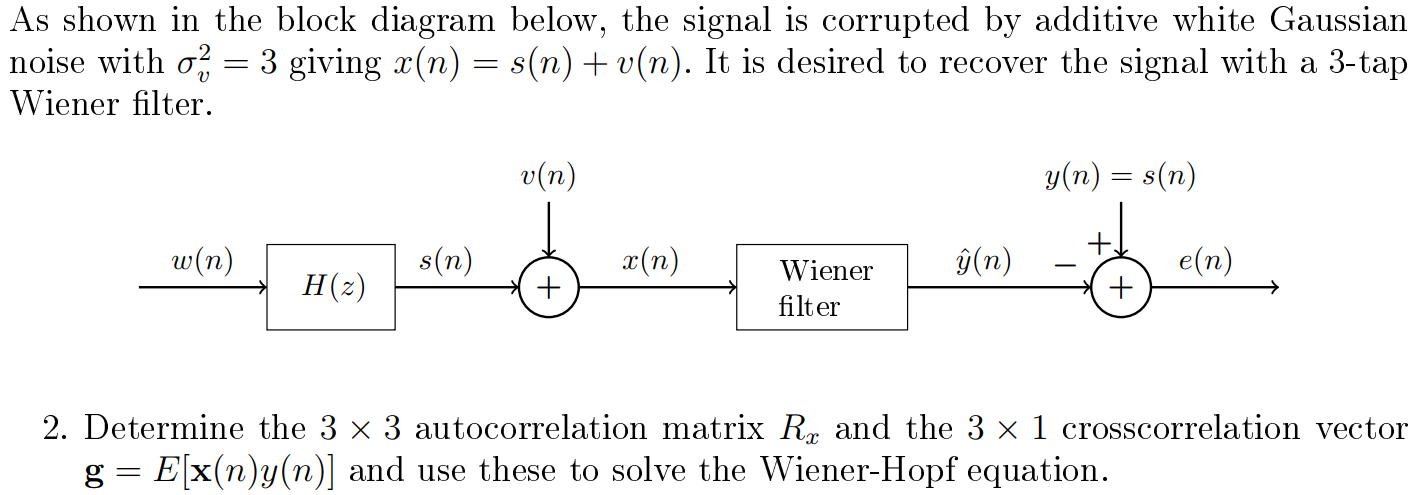

We know that $x\left(n\right)=s\left(n\right)+v\left(n\right)$ and $y\left(n\right)=s\left(n\right)=4w\left(n\right)+w\left(n-1\right)$

Assuming $w\left(n\right)$ and $v\left(n\right)$ are uncorrelated, the autocorrelation for $x\left(n\right)$:

        
$$r_x \left(\ell \right)=E\left\lbrack x\left(n\right)x\left(n-\ell \right)\right\rbrack$$


                 
$$=E\left\lbrack \left(s\left(n\right)+v\left(n\right)\right)\left(s\left(n-\ell \right)+v\left(n-\ell \right)\right)\right\rbrack$$


                 
$$=E\left\lbrack s\left(n\right)s\left(n-\ell \right)+s\left(n\right)v\left(n-\ell \right)+v\left(n\right)s\left(n-\ell \right)+v\left(n\right)v\left(n-\ell \right)\right\rbrack$$


                 
$$=E\left\lbrack s\left(n\right)s\left(n-\ell \right)\right\rbrack +E\left\lbrack s\left(n\right)v\left(n-\ell \right)\right\rbrack +E\left\lbrack v\left(n\right)s\left(n-\ell \right)\right\rbrack +E\left\lbrack v\left(n\right)v\left(n-\ell \right)\right\rbrack$$


                 
$$=r_s \left(\ell \right)+2r_{\mathrm{sv}} \left(\ell \right)+r_v \left(\ell \right)$$


                 $=r_s \left(\ell \right)+r_v \left(\ell \right)$ (because $w\left(n\right)$ and $v\left(n\right)$ are uncorrelated so $r_{\textrm{sv}} \left(\ell \right)=0$)

                 $=17\delta \left(\ell \right)+8\delta \left(\ell -1\right)+3\delta \left(\ell \right)$  -- $r_v \left(\ell \right)=3\delta \left(\ell \right)$ since $\sigma_v^2 =3$

                 
$$=20\delta \left(\ell \right)+8\delta \left(\ell -1\right)$$


We know that $x\left(n\right)=s\left(n\right)+v\left(n\right)$ and $y\left(n\right)=s\left(n\right)=4w\left(n\right)+w\left(n-1\right)$.

Compute the cross-correlation vector:

        
$$r_{\mathrm{xy}} \left(\ell \right)=E\left\lbrack x\left(n\right)y\left(n-\ell \right)\right\rbrack$$


                  
$$=E\left\lbrack \left(s\left(n\right)+v\left(n\right)\right)\left(4w\left(n-\ell \right)+w\left(n-\ell -1\right)\right)\right\rbrack$$


                  
$$=4E\left\lbrack s\left(n\right)w\left(n-\ell \right)\right\rbrack +E\left\lbrack s\left(n\right)w\left(n-\ell -1\right)\right\rbrack +4E\left\lbrack v\left(n\right)w\left(n-\ell \right)\right\rbrack +E\left\lbrack v\left(n\right)w\left(n-\ell -1\right)\right\rbrack$$


                  
$$=4r_{\mathrm{sw}} \left(\ell \right)+r_{\mathrm{sw}} \left(\ell -1\right)+4r_{\mathrm{vw}} \left(\ell \right)+r_{\mathrm{vw}} \left(\ell -1\right)$$


We assume that  $w\left(n\right)$ and $v\left(n\right)$ are uncorrelated so $r_{\textrm{vw}} \left(\ell \right)=0$:

                  
$$=4r_{\textrm{sw}} \left(\ell \right)+r_{\textrm{sw}} \left(\ell -1\right)+0+0$$


According to Eq. 13.100, the cross-correlation $r_{\textrm{sw}} \left(\ell \right)=\sigma_w^2 h\left(\ell \right)=h\left(\ell \right)$ since $\sigma_w^2 =1$. We know that the impulse response $h\left(\ell \right)=\left\lbrack 4,1\right\rbrack$:

                  
$$=4h\left(\ell \right)+h\left(\ell -1\right)$$


The third order Wiener filter for estimating the signal $y\left(n\right)$ is given by:

        
$$\hat{y} \left(n\right)=h_1 x\left(n\right)+h_2 x\left(n-1\right)+h_3 x\left(n-2\right)$$


The optimum Wiener filter to estimate a random process is given by Eq. 14.109:

        

where ${\mathit{\mathbf{R}}}_x$ is the correlation matrix of a random vector $\mathit{\mathbf{x}}$ and $\mathit{\mathbf{g}}$ is the cross-correlation vector between $\mathit{\mathbf{x}}$ and $y$

r_xx = [20, 8, 0];
R_xx = toeplitz(r_xx)

R_xx =     20     8     0
     8    20     8
     0     8    20


g = [4, 1, 0]'

g =      4
     1
     0


h_opt = R_xx\g

h_opt =     0.2176
   -0.0441
    0.0176


The optimal Wiener filter is given by:

        
$$H\left(z\right)=0\ldotp 2471-{0\ldotp 1176z}^{-1} +0\ldotp 0471z^{-2}$$


### [✔]  3) Discuss whether 3 taps is an optimum choice for this problem?

We can check whether the minimum mean square error can be lowered by using a longer Wiener filter.

Typically, increasing the length of the Wiener filter lowers the MSE which means that the filter becomes better 

The minimum value of the mean square error $E\left\lbrack e^2 \left(n\right)\right\rbrack E\left\lbrack {\left(y\left(n\right)-\hat{y} \left(n\right)\right)}^2 \right\rbrack$ is given by  

        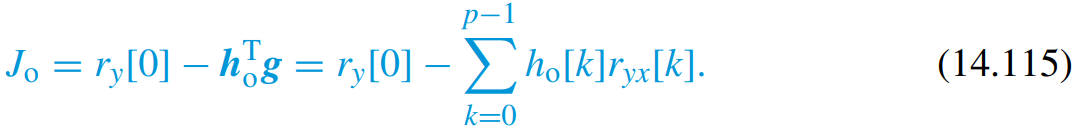

Let us compute it for a 3-tap Wiener filter:

mse_tap3 = r_ss(1) - h_opt'*g

Let us compute it for a 4-tap Wiener filter:

R_xx4 = toeplitz([r_xx, 0]);
g4 = [g', 0]';

$$ans = \frac{2\,a}{3}+\frac{1}{2}$$

h_opt4 = R_xx4\g4;
mse_tap4 = r_ss(1) - h_opt4'*g4

$$ans = \frac{3}{4}$$

Let us compute it for a 5-tap Wiener filter:

R_xx5 = toeplitz([r_xx, 0, 0]);

$$ans = 1$$

g5 = [g', 0, 0]';
h_opt5 = R_xx5\g5;
mse_tap5 = r_ss(1) - h_opt5'*g5

We observe that the minimum MSE can be lowered further by increasing the filter length. However, the decrease in minimum MSE is relatively small. If we want a faster filter, we would stick with 3-tap or even a 2-tap.

Let us compute it for a 2-tap Wiener filter:

R_xx2 = toeplitz(r_xx(1:2));

$$p = \frac{29}{128}$$

g2 = g(1:2);

$$ans = 0.2265625$$

h_opt2 = R_xx2\g2;
mse_tap2 = r_ss(1) - h_opt2'*g2

## Problem 5: Probability Density Function

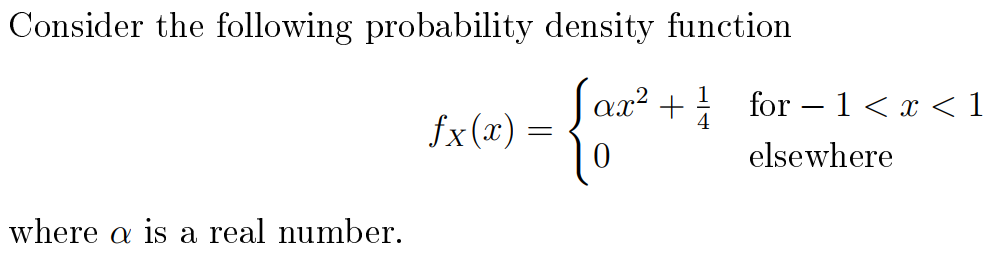

### [✔] 1) Find a valid probability density function

A valid probability density function is given by:

        
$$\int_{-\infty }^{\infty } f_X \left(x\right)\;\mathrm{dx}=1$$


We need to compute:

        
$$\int_{-1}^1 \alpha x^2 +\frac{1}{4}\textrm{dx}$$


For convenience and to avoid silly mistakes, use MATLAB:

syms x a
int(a*x^2 + 1/4, x, -1, 1)

$$f = \frac{3\,x^{2}\,{\mathrm{e}}^{-\left|x\right|}}{4}+\frac{1}{4}$$

Solve the equation for $a$ in MATLAB:

solve(int(a*x^2 + 1/4, x, -1, 1) - 1)

$$ans = \frac{7}{2}-\frac{15\,{\mathrm{e}}^{-1}}{2}$$

Let us check the results:

int(3/4 * x^2 + 1/4, x, -1, 1)

$$ans = 0.74090419121418258803357172378904$$

For $f_X \left(x\right)$ to be a valid probability density function, $a$ must be:

        
$$a=\frac{3}{4}$$


### [✔] 2) Compute the probability given a probability density function?

p = int(3/4 * x^2 + 1/4, x, 1/4, 3/4)
vpa(p)

The answer is:

        
$$\mathrm{Pr}\left(\frac{1}{4}<X\le \frac{3}{4}\right)=\frac{29}{128}=0\ldotp 2265625$$


### [✔] 3) Compute the expected value a function:

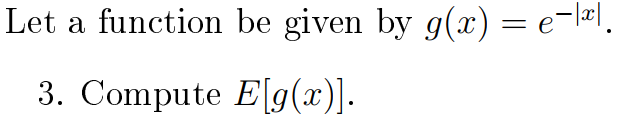

We need to compute:

        
$$E\left\lbrack g\left(x\right)\right\rbrack =\int_{-\infty \;}^{\infty } g\left(x\right)f_X \left(x\right)\;\mathrm{dx}=\int_{-1\;}^1 e^{-|x|} \cdot \frac{3}{4}x^2 +\frac{1}{4}\;\mathrm{dx}$$


syms x
f = exp(-abs(x)) * 3/4 * x^2 + 1/4
int(f , x, -1, 1 )
vpa(int(f , x, -1, 1 ))

The answer is:

        
$$E\left\lbrack g\left(x\right)\right\rbrack \approx 0\ldotp 74$$


## Functions

function [F, A, P, lambda_min]=pisarenko(r_xx, p)
    % Estimates the frequencies and amplitudes using the Pisarenko method
    %  r_xx: autocorrelation sequence starting from zero. 
    %        The length of ACRS must be at least 2p+1.
    %  p: assumed number of sinusoids in the signal
    %  F: normalised frequencies of the sinuoids
    %  A: amplitudes of the sinuoids
    if numel(r_xx) < 2*p+1
        error(strcat('The length of ACRS must be at least ', int2str(2*p+1)));
    end
    
    % Compute the autocorrelation matrix
    R_xx = toeplitz(r_xx(1:2*p+1));
    
    % Perform the eigendecomposition
    [eigvecs, eigvals] = eigs(R_xx, size(R_xx, 1), 'smallestreal');
    
    eigvals = diag(eigvals);
    lambda_min = eigvals(1);
    
    % Find the eigenvector 'a' corresponding to the smallest eigenvalue.
    % The function eigs() sorts eigenvectors, so just pick the first column.
    a = eigvecs(:, 1);
    
    % Ensure that a_0 = 1 (this is by definition)
    a = a / a(1);
    
    % The elements of this eigenvector corresponds to the parameters
    % of an ARMA(2p, 2p) model: a_0, a_1, ..., a_2p where p: number of sinusoids
    % The polynomial A(z) in (14.5.4) has 2p poles on the unit circle.
    % Obtain the poles by finding the roots of the system.
    z = roots(a);
    
    % Estimate frequencies
    F = zeros(p, 1);
    for i = 1:p
        % The poles come in pairs. Each pair is complex conjugate
        % of one another. Only use one of them and find the absolute value.
        z_i = z(2*i);
        F(i) = abs(angle(z_i)) / (2*pi);
    end
    
    % Build the matrix of cosines
    C = zeros(p);
    for i = 1:p
        for j = 1:p
            C(i, j) = cos(i * 2*pi * F(j));
        end
    end
    
    % Start the ACRS from the second element according to equation (14.5.11)
    gamma = r_xx(2:p+1);
    
    % Solve equation (14.5.11) for P
    P = C\gamma; % Same as `inv(C)*gamma` but faster and more accurate
    
    % Since P=A^2/2, we can compute the amplitude A=sqrt(2*P)
    A = sqrt(2 * P);
end